clear;  clc;    

% Defining points (x y z)
basePoint =      [0 0 0];
hoverBasePoint = [0 0 -5];
hoverTree1 =     [2 2 -5];
hoverTree2 =     [2 4 -5];
hoverTree3 =     [4 2 -5];

% Defining route of points
points = [basePoint;
          hoverBasePoint;
          hoverTree1;
          hoverTree2;
          hoverTree3;
          hoverBasePoint;
          basePoint]'

points =      0     0     2     2     4     0     0
     0     0     2     4     2     0     0
     0    -5    -5    -5    -5    -5     0


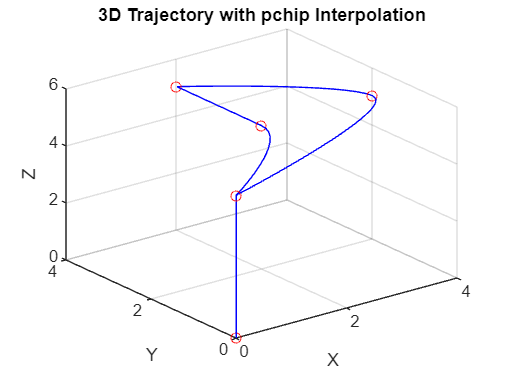


% Define parameter t for each point
numPoints = size(points, 2);
t = linspace(0, 1, numPoints);

% Interpolating for x, y, and z coordinates
pchipX = pchip(t, points(1, :));
pchipY = pchip(t, points(2, :));
pchipZ = pchip(t, points(3, :));

% Define a fine grid for smooth plotting
tFine = linspace(0, 1, 100);

% Evaluate the spline at the fine grid points
xFine = ppval(pchipX, tFine);
yFine = ppval(pchipY, tFine);
zFine = ppval(pchipZ, tFine);

% Plot the curve and original points
plot3(points(1, :), points(2, :), -points(3, :), 'ro'); % Original points
hold on;
plot3(xFine, yFine, -zFine, 'b-'); % Interpolated curve
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Trajectory with pchip Interpolation');
grid on;


% Extracting the coefficients [a b c d] and breakpoints for 
% a piecewise cubic polynomial

% Coefficients for each segment (rows correspond to segments)
xCoefs = pchipX.coefs;
yCoefs = pchipY.coefs;
zCoefs = pchipZ.coefs;

% Breakpoints for intervals
xBreaks = pchipX.breaks;
yBreaks = pchipY.breaks;
zBreaks = pchipZ.breaks;

